# **Functions and function handles**

Some parts adapted from MATLAB Master Class, Mike Agostini

## **What kind of thing is fh?**

%%
fh = @cos;
% Use it like any other function.
fh(pi)

ans = -1

## **Why do we want to use function handles?**

- Allows your function to be a variable and pass them as args to another function. e.g. `integral`

- Specify callback functions (executed at specific time). 

- Define inline functions

- Call local functions from outside the main function

## **What about this?**

a = 2;
b = 3;
fh = @(x) a*x+b;

% Plot and see result
fh(1:5)

ans =      5     7     9    11    13


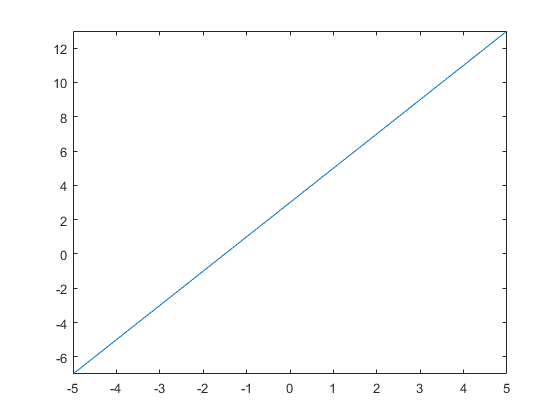

fplot(fh)

An anonymous function allows defining functions on the fly without saving them on the file. 

You can compute its integral too.

integral(fh,0,1)

ans = 4.0000

## More fun with functions

What if I do this? What will the command window show now?

a = 100;
b = 0;
fh(1)

ans = 5

Does your function change when the variables that were part of its definition change? 

## Get all information about the function

F = functions(fh)

F = struct with fields:
            function: '@(x)a*x+b'
                type: 'anonymous'
                file: 'C:\Users\vsh3681\AppData\Local\Temp\Editor\LiveEditorEvaluationHelperEID1421483844.mlx'
           workspace: {[1×1 struct]}
    within_file_path: 'LiveEditorEvaluationHelperEID1421483844'


F.workspace{1}

ans = struct with fields:
    a: 2
    b: 3


## Subfunctions

You can create functions within a function script? But why? 

Can subfunctions access variables from the parent function?

open subfunc1.m
open subfunc2.m

## What if I want a function that keeps track of its history?

a = 3;
b = 2;
open subfunc3.m


## Persistent Variables

What if I do not want to declare a variable for all functions in my script, yet I want MATLAB to remember that variable between successive calls of a function?

open addnum.m